# Solve an Overdetermined System

Instructions are in the task pane to the left. Complete and submit each task one at a time. 

This code plots the lines.

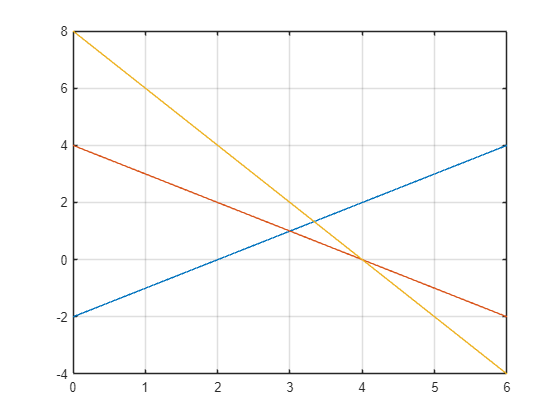

x = linspace(0, 6);
plot(x, x-2)
hold on
grid on
plot(x, 4-x)
plot(x, 8-2*x)
hold off

## Task 1

In this activity, you will solve an overdetermined system of equations. The equations can be visualized as three lines, and the lines have been plotted for you. By examining the plot, you can see that the three lines do not all intersect at a single point.

Consider the following system of equations:

*x*−*y*=2

*x*+*y*=42

*x*+*y*=8

A = [1 -1; 1 1; 2 1];

## Task 2

The system of equations is

*x*−*y*=2

*x*+*y*=4

2*x*+*y*=8

b = [2; 4; 8];

## Task 3

The system of equations has now been rewritten as a single matrix equation:


$$\left\lbrack \begin{array}{cc}
1 & -1\\
1 & 1\\
2 & 1
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
4\\
8
\end{array}\right\rbrack$$


You can solve for **x** using the backslash operator (`\`). Because the system is overdetermined, `\` will try to find the best solution using least squares.

point = A\b;

## Task 4

The variable `point` is a two-element vector. The first element is the *x* value of the solution, and the second element is the *y* value of the solution.

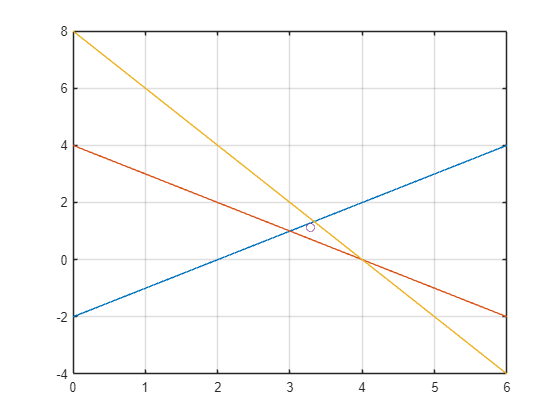

hold on
plot(point(1), point(2), "o")
grid on
hold off